files = ["data20", "data-20", "data40", "data-40", "data60", "data-60", "data80", "data-80", "data100", "data-100"]; %
voltages = [20, -20, 40, -40, 60, -60, 80, -80, 100, -100]; 

## Plot for approximation with original of angle(t)

    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    0.1000
    0.8400




Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


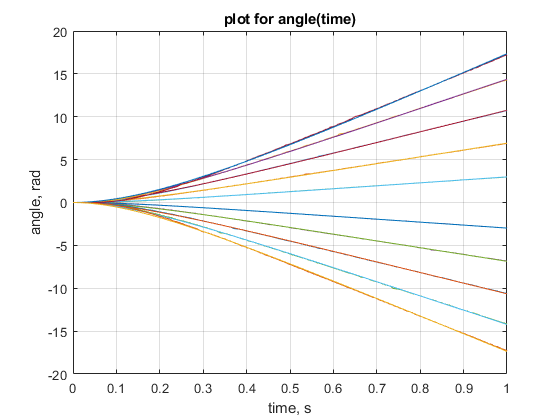


for i=1:10
    data = readmatrix(files(i));
    time=data(:,1);
    U = voltages(i);
    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    
    title("plot for angle(time)")
    plot(time,angle);
    xlabel("time, s")
    ylabel("angle, rad")
    xlim([0 1]);
    grid on
    
    hold on
    % some coeficients for approximation - let's take...
    lol = [0.1 ; 0.84];
    U_pr = 100;
    func = @(lol, time) U_pr*lol(1)*(time - lol(2)*(1 - exp(-time/lol(2))));
    disp(lol);
    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,lol,time,angle);
    k = solver(1);
    Tm = solver(2);
  
    time_apr = 0:0.01:1;
    theta = U_pr*k*(time_apr - (Tm*(1 - exp(-time_apr/Tm))));
    plot(time_apr,theta);

   

    
   
end